clear;
% Locate target folder inside Box / Box-Box (upward search first; then ~/Library/CloudStorage fallback)
targetSubfolder = 'Parrish_lab_folder';
startPath = pwd;
foundPath = '';

boxNames = {'Box','Box-Box'};

%% -------- Attempt 1: search upward from pwd, looking for Box / Box-Box at each level
currentPath = startPath;

while true
    for iB = 1:numel(boxNames)
        candidateBox = fullfile(currentPath, boxNames{iB});
        if isfolder(candidateBox)
            % Direct child?
            candidateTarget = fullfile(candidateBox, targetSubfolder);
            if isfolder(candidateTarget)
                foundPath = candidateTarget;
                break;
            end

            % Search downward within this Box root
            listing = dir(fullfile(candidateBox, '**', targetSubfolder));
            listing = listing([listing.isdir]);
            if ~isempty(listing)
                foundPath = fullfile(listing(1).folder, listing(1).name);
                break;
            else
                warning('Found "%s" at %s but not "%s" inside it.', boxNames{iB}, candidateBox, targetSubfolder);
            end
        end
    end

    if ~isempty(foundPath)
        break;
    end

    parentPath = fileparts(currentPath);
    if strcmp(parentPath, currentPath)
        % Reached filesystem root
        break;
    end
    currentPath = parentPath;
end

%% -------- Attempt 2 (fallback): go to user home -> ~/Library/CloudStorage -> Box / Box-Box / Box*
if isempty(foundPath)
    % Robust "home" across platforms
    homeDir = char(java.lang.System.getProperty('user.home'));

    cloudDir = fullfile(homeDir, 'Library', 'CloudStorage');

    if isfolder(cloudDir)
        % Collect candidate Box roots: exact + any Box* folders inside CloudStorage
        boxRoots = {};

        % Prefer the exact names first (if present)
        for iB = 1:numel(boxNames)
            p = fullfile(cloudDir, boxNames{iB});
            if isfolder(p), boxRoots{end+1} = p; end %#ok<AGROW>
        end

        % Also include any "Box*" folders (e.g., Box-Box, Box Sync, etc.)
        d = dir(cloudDir);
        d = d([d.isdir]);
        d = d(~ismember({d.name},{'.','..'}));
        boxLike = d(startsWith({d.name}, 'Box', 'IgnoreCase', true));
        for k = 1:numel(boxLike)
            p = fullfile(boxLike(k).folder, boxLike(k).name);
            if ~any(strcmp(boxRoots, p))
                boxRoots{end+1} = p; %#ok<AGROW>
            end
        end

        % Search each candidate Box root for the target
        for k = 1:numel(boxRoots)
            root = boxRoots{k};

            candidateTarget = fullfile(root, targetSubfolder);
            if isfolder(candidateTarget)
                foundPath = candidateTarget;
                break;
            end

            listing = dir(fullfile(root, '**', targetSubfolder));
            listing = listing([listing.isdir]);
            if ~isempty(listing)
                foundPath = fullfile(listing(1).folder, listing(1).name);
                break;
            end
        end
    end
end

%% -------- Report
if isempty(foundPath)
    warning('Could not find "%s" inside Box/Box-Box (upward from "%s") or under ~/Library/CloudStorage.', ...
        targetSubfolder, startPath);
else
    fprintf('Found folder: %s\n', foundPath);
end

Found folder: C:\Users\jhn25\Box\Parrish_lab_folder


sourcepath = fullfile(foundPath,"\Utah-array-NCL\Utah Array Recs\MEA recordings");

paths = list_large_mat_files(sourcepath, 100000);      % >100,000 KB

[mainDir,~] = fileparts(fileparts(sourcepath));
savefolderName = 'Converted Utah Array Files';
saveFolder = fullfile(mainDir,savefolderName);

if exist(saveFolder, 'dir')
    fprintf('Figure folder directory exists:\n %s',saveFolder);
else
    mkdir(mainDir,savefolderName);
end

Figure folder directory exists:
 C:\Users\jhn25\Box\Parrish_lab_folder\Utah-array-NCL\Utah Array Recs\MEA recordings\Converted Utah Array Files

for ii = 1:numel(paths)
    try
        filepath = paths{ii};

        try

            [~,filename] = fileparts(filepath);

            data = load(fullfile(filepath));

            root = data;
            if ~isstruct(root)
                error("Root variable '%s' is not a struct.", rootVarName);
            end
            
            % --- FIND FIELDS CONTAINING 'rec' ---
            allFields = fieldnames(root);
            isRecField = contains(allFields, "rec");   % case-sensitive; use lower() for case-insensitive
            recFields  = allFields(isRecField);
            
            % --- EXTRACT ---
            out = struct('fullFieldName', {}, 'prefix', {}, 'ElecID', {}, 'data', {});
            k = 0;
            
            for i = 1:numel(recFields)
                f = recFields{i};
                recStruct = root.(f);
            
                % Only proceed if this field is a struct with ElecID and data inside
                if ~isstruct(recStruct) || ~isfield(recStruct, "ElecID") || ~isfield(recStruct, "data")
                    continue
                end
            
                % Prefix = part before the first occurrence of "rec"
                idx = strfind(f, "rec");
                prefix = f(1:idx(1)-1);
            
                % Pull fields
                ElecID = recStruct.ElecID;
                data   = recStruct.data;
            
                % Optional sanity checks (comment out if you don't want them)
                if ~isnumeric(ElecID) || size(ElecID,2) ~= 1
                    warning("Field %s: ElecID is not an n×1 numeric array.", f);
                end
                if ~isnumeric(data)
                    warning("Field %s: data is not numeric.", f);
                end
            
                k = k + 1;
                out(k).fullFieldName = f;
                out(k).prefix        = prefix;
                out(k).ElecID        = ElecID;
                out(k).data          = data;
            end
            
            % --- OPTIONAL: ALSO MAKE A PREFIX-KEYED STRUCT FOR QUICK ACCESS ---
            byPrefix = struct();
            for i = 1:numel(out)
                p = out(i).prefix;
                if p == ""
                    p = "noPrefix";
                end
            
                % Ensure valid MATLAB fieldname
                pField = matlab.lang.makeValidName(p);
            
                % If multiple rec-fields share the same prefix, store as an array
                if isfield(byPrefix, pField)
                    byPrefix.(pField)(end+1) = out(i);
                else
                    byPrefix.(pField) = out(i);
                end
            end

            fs = 1000; %set fs

            % --- 1) combined matrix of all data ---
            dataAll = vertcat(out.data);      % (a_total x m)
            
            % --- 2) combined ElecID list in matching order ---
            elecIDAll = vertcat(out.ElecID);  % (a_total x 1)
            
            % --- Optional safety checks ---
            if size(dataAll,1) ~= numel(elecIDAll)
                error("Row mismatch: dataAll has %d rows but elecIDAll has %d elements.", ...
                    size(dataAll,1), numel(elecIDAll));
            end
            
            % If you want to enforce consistent column count m across all entries:
            mList = cellfun(@(x) size(x,2), {out.data});
            if any(mList ~= mList(1))
                error("Not all out(i).data have the same number of columns (m).");
            end

            % Elec_ID_all -> (row,col) coordinates on a 10x10 grid with 4 missing corners
            % Missing: (1,1), (1,10), (10,1), (10,10)
            % Indexing order:
            %   1–8   -> row 1, cols 2–9
            %   9–88  -> rows 2–9, cols 1–10 (10 per row)
            %   89–96 -> row 10, cols 2–9
            
            idx = elecIDAll(:);                 % ensure a x 1
            coords_rc = nan(numel(idx), 2);       % [row col]
            isValid = isfinite(idx) & idx==floor(idx) & idx>=1 & idx<=96;
            
            % --- top row: 1..8 -> (1, 2..9)
            m1 = isValid & (idx <= 8);
            coords_rc(m1,1) = 1;
            coords_rc(m1,2) = idx(m1) + 1;
            
            % --- middle rows: 9..88 -> rows 2..9, cols 1..10
            m2 = isValid & (idx >= 9) & (idx <= 88);
            t = idx(m2) - 9;                      % 0..79
            coords_rc(m2,1) = floor(t/10) + 2;    % 2..9
            coords_rc(m2,2) = mod(t,10) + 1;      % 1..10
            
            % --- bottom row: 89..96 -> (10, 2..9)
            m3 = isValid & (idx >= 89);
            coords_rc(m3,1) = 10;
            coords_rc(m3,2) = (idx(m3) - 89) + 2; % 2..9
            
            % coords_rc is a x 2, row-for-row aligned with Elec_ID_all
            % isValid tells you which indices mapped cleanly (others stay NaN)

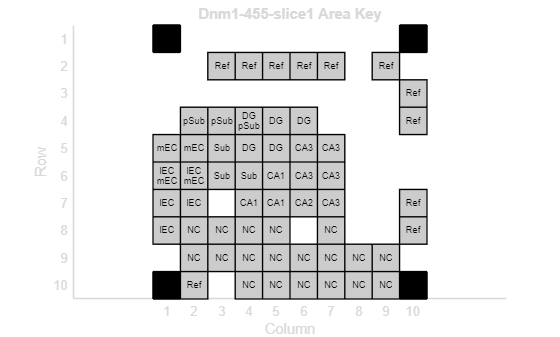

            %% ASSUMES YOU ALREADY HAVE:
            % out        : struct array with out(i).prefix, out(i).ElecID, out(i).data
            % Elec_ID_all: a x 1 (from vertcat(out.ElecID))
            % coords_rc  : a x 2 [row col] (from your index->grid mapping)
            
            %% 1) Build a per-row prefix list aligned with Elec_ID_all / coords_rc
            nPer = arrayfun(@(s) size(s.data,1), out);     % rows contributed by each out(i)
            prefixAll = cell(sum(nPer),1);
            
            p = 0;
            for i = 1:numel(out)
                n = nPer(i);
                prefixAll(p+(1:n)) = {out(i).prefix};     % repeat prefix for each row
                p = p + n;
            end
            
            % Safety check
            if size(coords_rc,1) ~= numel(prefixAll)
                error("coords_rc rows (%d) and prefixAll length (%d) do not match.", ...
                    size(coords_rc,1), numel(prefixAll));
            end
            
            %% 2) Aggregate labels per grid cell (in case multiple rows land on same cell)
            valid = all(isfinite(coords_rc),2);
            rows  = coords_rc(valid,1);
            cols  = coords_rc(valid,2);
            labs  = prefixAll(valid);
            
            labelMap = containers.Map('KeyType','char','ValueType','any'); % value = cellstr list
            
            for i = 1:numel(rows)
                key = sprintf('%d_%d', rows(i), cols(i));
            
                if isKey(labelMap, key)
                    tmp = labelMap(key);      % get existing cell array
                    tmp{end+1} = labs{i};     % append
                    labelMap(key) = tmp;      % set back
                else
                    labelMap(key) = {labs{i}};
                end
            end
            
            %% 3) Plot 10x10 grid, black out corners, and place centered text labels
            figure('Color','w'); clf; hold on;
            
            % Grid extents and orientation (row 1 at top)
            axis([0.5 10.5 0.5 10.5]);
            axis equal;
            set(gca,'YDir','reverse', 'XTick',1:10, 'YTick',1:10, 'TickLength',[0 0]);
            grid on;
            
            % Black out missing corners: (1,1), (1,10), (10,1), (10,10)
            missing = [1 1; 1 10; 10 1; 10 10]; % [row col]
            for k = 1:size(missing,1)
                r = missing(k,1); c = missing(k,2);
                rectangle('Position',[c-0.5 r-0.5 1 1], 'FaceColor','k', 'EdgeColor','k');
            end
            
            % (Optional) show all points as markers
            % --- draw filled cell patches (1x1 squares) for each occupied coordinate ---
            valid = all(isfinite(coords_rc),2);
            rows  = coords_rc(valid,1);
            cols  = coords_rc(valid,2);
            
            for i = 1:numel(rows)
                r = rows(i); c = cols(i);
                rectangle('Position', [c-0.5, r-0.5, 1, 1], ...
                    'FaceColor', [0.8 0.8 0.8], ...   % pick any fill color
                    'EdgeColor', 'k', ...
                    'LineWidth', 1);
            end
            % Put text labels centered in each occupied cell
            keys = labelMap.keys;
            for k = 1:numel(keys)
                key = keys{k};
                parts = sscanf(key, '%d_%d');
                r = parts(1); c = parts(2);
            
                cellLabs = labelMap(key);
                cellLabs = unique(cellLabs, 'stable');           % avoid repeats
                txt = strjoin(cellLabs, newline);                % stack labels if >1
            
                text(c, r, txt, ...
                    'HorizontalAlignment','center', ...
                    'VerticalAlignment','middle', ...
                    'FontSize', 7, 'Interpreter','none','Color','k');
            end
            
            title(sprintf('%s Area Key',strrep(filename,'_','-')));
            xlabel('Column'); ylabel('Row');
            set(gca,'Color','w')
            hold off;
            saveas(gcf,fullfile(saveFolder,sprintf('%s-AreaKey.png',strrep(filename,'_','-'))));

            [~,fName] = fileparts(filename);
            create_brw_strict(fullfile(saveFolder,[fName '-CONV.brw']), dataAll/1000, coords_rc);
        catch ME_inner
            % Save per-file error and keep going
            [pDir, pBase] = fileparts(filepath);
            errFile = fullfile(saveFolder, sprintf('%s_ERROR.mat', pBase));
            save(errFile, 'ME_inner', 'filepath');
        end

    catch ME_outer
        % If something even above fails (e.g., saveFolder missing), still log it
        safeErrDir = tempdir;
        errFile = fullfile(safeErrDir, sprintf('BRW_BATCH_ERROR_%04d.mat', ii));
        save(errFile, 'ME_outer', 'ii');
    end
end

✅ Wrote strict .brw: C:\Users\jhn25\Box\Parrish_lab_folder\Utah-array-NCL\Converted Utah Array Files\Dnm1_455_slice1-CONV.brw
   nCh=107, NSamp=3246709, Raw length=347397863 (rank-1)


function create_brw_strict(outFile, dataAll, coords_rc)
%CREATE_BRW_STRICT Create a strict BRW-like HDF5 file (no template needed).
%
% Inputs:
%   outFile   : output filename ('.brw' optional)
%   dataAll   : nCh x NSamp double
%   coords_rc : nCh x 2 double, [row col] per channel (already final coords)
%
% Raw flattening order is time-interleaved by channel (matches read_and_clean):
%   full_data(i:total_channels:end) reconstructs channel i

    % -------------------------
    % Hard-coded constants (match your Python)
    % -------------------------
    sampling_rate_hz = 1000.0;
    max_volt = 4125.0;
    min_volt = -4125.0;
    bit_depth = uint8(12);

    % -------------------------
    % Validate inputs
    % -------------------------
    if ~(isnumeric(dataAll) && ismatrix(dataAll))
        error('dataAll must be a numeric 2D matrix (nCh x NSamp).');
    end
    if ~(isnumeric(coords_rc) && size(coords_rc,2) == 2)
        error('coords_rc must be nCh x 2 numeric [row col].');
    end

    nCh   = size(dataAll,1);
    NSamp = size(dataAll,2);

    if size(coords_rc,1) ~= nCh
        error('coords_rc rows (%d) must match dataAll rows (%d).', size(coords_rc,1), nCh);
    end
    if any(~isfinite(dataAll(:)))
        error('dataAll contains NaN/Inf. Replace/remove before writing.');
    end

    % Normalize output name
    if ~endsWith(lower(string(outFile)), ".brw")
        outFile = string(outFile) + ".brw";
    end
    outFile = char(outFile);

    [outDir, base, ext] = fileparts(outFile);
    if isempty(outDir)
        outDir = pwd;
        outFile = fullfile(outDir, [base ext]);
    end

    % Quick write-permission test for destination folder
    testPath = fullfile(outDir, '__brw_write_test.tmp');
    [fid, msg] = fopen(testPath, 'w');
    if fid < 0
        error("No write permission (or folder locked) for destination:\n%s\nfopen error: %s", outDir, msg);
    end
    fclose(fid);
    delete(testPath);

    % Write to temp file first (more robust with Box/Sync locks)
    tmpFile = [tempname '.brw'];
    if exist(tmpFile, 'file'); delete(tmpFile); end

    try
        % -------------------------
        % 1) Flatten in order your read_and_clean expects
        %    dataAll(:) -> [ch1(t1), ch2(t1), ... chN(t1), ch1(t2), ...]
        % -------------------------
        traceFloat = double(dataAll(:));  % (nCh*NSamp) x 1

        % -------------------------
        % 2) Scale to int16 exactly like Python np.interp(min->minint16, max->maxint16)
        % -------------------------
        i16min = double(intmin('int16')); % -32768
        i16max = double(intmax('int16')); %  32767
        mn = min(traceFloat);
        mx = max(traceFloat);

        if mx == mn
            scaled_trace = int16(zeros(size(traceFloat)));
        else
            scaled = (traceFloat - mn) ./ (mx - mn);
            scaled = scaled .* (i16max - i16min) + i16min;
            scaled_trace = int16(round(scaled));
        end

        % -------------------------
        % 3) Write simple numeric datasets (high-level)
        % -------------------------
        % /3BData/Raw MUST be rank-1 (N,) — not (N,1) or (1,N)
        scaled_trace = scaled_trace(:);
        Nraw = numel(scaled_trace);
        h5create(tmpFile, '/3BData/Raw', double(Nraw), 'Datatype', 'int16');
        h5write(tmpFile,  '/3BData/Raw', scaled_trace);

        % /3BRecInfo/3BMeaChip/*
        layout = ones(64,64,'uint8');
        h5create(tmpFile, '/3BRecInfo/3BMeaChip/Layout', size(layout), 'Datatype', 'uint8');
        h5write(tmpFile,  '/3BRecInfo/3BMeaChip/Layout', layout);

        h5create(tmpFile, '/3BRecInfo/3BMeaChip/MeaType', [1 1], 'Datatype', 'int32');
        h5write(tmpFile,  '/3BRecInfo/3BMeaChip/MeaType', int32(65536));

        h5create(tmpFile, '/3BRecInfo/3BMeaChip/NCols', [1 1], 'Datatype', 'uint32');
        h5write(tmpFile,  '/3BRecInfo/3BMeaChip/NCols', uint32(64));

        h5create(tmpFile, '/3BRecInfo/3BMeaChip/NRows', [1 1], 'Datatype', 'uint32');
        h5write(tmpFile,  '/3BRecInfo/3BMeaChip/NRows', uint32(64));

        % /3BRecInfo/3BMeaSystem/System
        h5create(tmpFile, '/3BRecInfo/3BMeaSystem/System', [1 1], 'Datatype', 'int32');
        h5write(tmpFile,  '/3BRecInfo/3BMeaSystem/System', int32(1));

        % /3BRecInfo/3BRecVars/*
        h5create(tmpFile, '/3BRecInfo/3BRecVars/BitDepth', [1 1], 'Datatype', 'uint8');
        h5write(tmpFile,  '/3BRecInfo/3BRecVars/BitDepth', bit_depth);

        h5create(tmpFile, '/3BRecInfo/3BRecVars/ExperimentType', [1 1], 'Datatype', 'int32');
        h5write(tmpFile,  '/3BRecInfo/3BRecVars/ExperimentType', int32(0));

        h5create(tmpFile, '/3BRecInfo/3BRecVars/MaxVolt', [1 1], 'Datatype', 'double');
        h5write(tmpFile,  '/3BRecInfo/3BRecVars/MaxVolt', double(max_volt));

        h5create(tmpFile, '/3BRecInfo/3BRecVars/MinVolt', [1 1], 'Datatype', 'double');
        h5write(tmpFile,  '/3BRecInfo/3BRecVars/MinVolt', double(min_volt));

        h5create(tmpFile, '/3BRecInfo/3BRecVars/NRecFrames', [1 1], 'Datatype', 'int64');
        h5write(tmpFile,  '/3BRecInfo/3BRecVars/NRecFrames', int64(NSamp));

        h5create(tmpFile, '/3BRecInfo/3BRecVars/SamplingRate', [1 1], 'Datatype', 'double');
        h5write(tmpFile,  '/3BRecInfo/3BRecVars/SamplingRate', double(sampling_rate_hz));

        h5create(tmpFile, '/3BRecInfo/3BRecVars/SignalInversion', [1 1], 'Datatype', 'double');
        h5write(tmpFile,  '/3BRecInfo/3BRecVars/SignalInversion', double(1.0));

        % -------------------------
        % 4) Write strict compound + vlen-string datasets (low-level HDF5)
        % -------------------------
        file_id = H5F.open(tmpFile, 'H5F_ACC_RDWR', 'H5P_DEFAULT');
        try
            % SysChs: single element compound(Row int16, Col int16) with (1,1)
            write_compound_rowcol(file_id, '/3BRecInfo/3BMeaChip/SysChs', int16(1), int16(1));

            % Chs: compound(Row int16, Col int16) length nCh using coords_rc directly (NO +1*6)
            rows = int16(round(coords_rc(:,1)));
            cols = int16(round(coords_rc(:,2)));
            write_compound_rowcol(file_id, '/3BRecInfo/3BMeaStreams/Raw/Chs', rows, cols);

            % FwVersion / HwVersion: compound 4x int32
            write_compound_fw(file_id, '/3BRecInfo/3BMeaSystem/FwVersion', int32(1), int32(4), int32(1), int32(4));
            write_compound_fw(file_id, '/3BRecInfo/3BMeaSystem/HwVersion', int32(3), int32(0), int32(-1), int32(-1));

            % Empty strict ROIs / ExpMarkers / ExpNotes (compound with nested compound + vlen UTF-8 strings)
            create_empty_strict_datasets(file_id);

        catch ME
            H5F.close(file_id);
            rethrow(ME);
        end
        H5F.close(file_id);

        % -------------------------
        % 5) Move temp into destination (handle Box locks)
        % -------------------------
        if exist(outFile, 'file')
            delete(outFile);
        end

        [ok, msg] = movefile(tmpFile, outFile, 'f');
        if ~ok
            % If move fails (common in sync folders), try copy+delete
            [ok2, msg2] = copyfile(tmpFile, outFile, 'f');
            if ok2
                delete(tmpFile);
            else
                error("Failed to write destination (file may be locked/open):\n%s\nmovefile: %s\ncopyfile: %s", outFile, msg, msg2);
            end
        end

        fprintf('✅ Wrote strict .brw: %s\n', outFile);
        fprintf('   nCh=%d, NSamp=%d, Raw length=%d (rank-1)\n', nCh, NSamp, Nraw);

    catch ME
        if exist(tmpFile, 'file')
            try, delete(tmpFile); catch, end %#ok<CTCH>
        end
        rethrow(ME);
    end
end

% ========================================================================
% Low-level helpers (drop-in replacements)
% ========================================================================

function gid = ensure_group(file_id, groupPath)
    % Create/open nested groups under root, return group id of final group.
    if strcmp(groupPath, '/') || isempty(groupPath)
        gid = H5G.open(file_id, '/');
        return;
    end

    parts = split(string(groupPath), '/');
    parts = parts(parts ~= "");
    curr = H5G.open(file_id, '/');

    for i = 1:numel(parts)
        name = char(parts(i));
        if H5L.exists(curr, name, 'H5P_DEFAULT')
            next = H5G.open(curr, name);
        else
            next = H5G.create(curr, name, 'H5P_DEFAULT', 'H5P_DEFAULT', 'H5P_DEFAULT');
        end
        H5G.close(curr);
        curr = next;
    end
    gid = curr;
end

function write_compound_rowcol(file_id, dsetPath, rowVals, colVals)
    rowVals = int16(rowVals(:));
    colVals = int16(colVals(:));
    if numel(rowVals) ~= numel(colVals)
        error('Row/Col sizes must match.');
    end
    N = numel(rowVals);

    [grpPath, name] = split_h5_path(dsetPath);
    gid = ensure_group(file_id, grpPath);
    gc = onCleanup(@() H5G.close(gid));

    % File datatype: compound(Row int16, Col int16) little-endian like '<i2'
    t_i16 = H5T.copy('H5T_STD_I16LE');
    t_cmp = H5T.create('H5T_COMPOUND', 4);
    H5T.insert(t_cmp, 'Row', 0, t_i16);
    H5T.insert(t_cmp, 'Col', 2, t_i16);
    H5T.pack(t_cmp);

    tc1 = onCleanup(@() H5T.close(t_cmp));
    tc2 = onCleanup(@() H5T.close(t_i16));

    space_id = H5S.create_simple(1, double(N), []);
    sc = onCleanup(@() H5S.close(space_id));

    dset_id = H5D.create(gid, name, t_cmp, space_id, 'H5P_DEFAULT');
    dc = onCleanup(@() H5D.close(dset_id));

    % ✅ struct-of-arrays (MATLAB-friendly)
    buf = struct();
    buf.Row = rowVals;   % N x 1
    buf.Col = colVals;   % N x 1
    H5D.write(dset_id, t_cmp, 'H5S_ALL', 'H5S_ALL', 'H5P_DEFAULT', buf);
end

function write_compound_fw(file_id, dsetPath, Major, Minor, Build, Revision)
    [grpPath, name] = split_h5_path(dsetPath);
    gid = ensure_group(file_id, grpPath);
    gc = onCleanup(@() H5G.close(gid));

    t_i32 = H5T.copy('H5T_STD_I32LE');
    t_cmp = H5T.create('H5T_COMPOUND', 16);
    H5T.insert(t_cmp, 'Major',    0,  t_i32);
    H5T.insert(t_cmp, 'Minor',    4,  t_i32);
    H5T.insert(t_cmp, 'Build',    8,  t_i32);
    H5T.insert(t_cmp, 'Revision', 12, t_i32);
    H5T.pack(t_cmp);

    tc1 = onCleanup(@() H5T.close(t_cmp));
    tc2 = onCleanup(@() H5T.close(t_i32));

    space_id = H5S.create_simple(1, double(1), []);
    sc = onCleanup(@() H5S.close(space_id));

    dset_id = H5D.create(gid, name, t_cmp, space_id, 'H5P_DEFAULT');
    dc = onCleanup(@() H5D.close(dset_id));

    buf = struct();
    buf.Major    = int32(Major);
    buf.Minor    = int32(Minor);
    buf.Build    = int32(Build);
    buf.Revision = int32(Revision);
    H5D.write(dset_id, t_cmp, 'H5S_ALL', 'H5S_ALL', 'H5P_DEFAULT', buf);
end

function create_empty_strict_datasets(file_id)
    % vlen UTF-8 string type (like h5py.string_dtype(encoding="utf-8"))
    vlen_str = H5T.copy('H5T_C_S1');
    H5T.set_size(vlen_str, 'H5T_VARIABLE');
    H5T.set_cset(vlen_str, H5ML.get_constant_value('H5T_CSET_UTF8'));
    H5T.set_strpad(vlen_str, H5ML.get_constant_value('H5T_STR_NULLTERM'));
    vlen_sz = H5T.get_size(vlen_str); % pointer size (typically 8)

    % Base integer types
    t_i32 = H5T.copy('H5T_STD_I32LE');
    t_u8  = H5T.copy('H5T_STD_U8LE');
    t_i16 = H5T.copy('H5T_STD_I16LE');
    t_i64 = H5T.copy('H5T_STD_I64LE');

    % Color compound: KnownColor int32, Alpha/Red/Green/Blue uint8
    color_t = H5T.create('H5T_COMPOUND', 8);
    H5T.insert(color_t, 'KnownColor', 0, t_i32);
    H5T.insert(color_t, 'Alpha',      4, t_u8);
    H5T.insert(color_t, 'Red',        5, t_u8);
    H5T.insert(color_t, 'Green',      6, t_u8);
    H5T.insert(color_t, 'Blue',       7, t_u8);
    H5T.pack(color_t);
    color_sz = H5T.get_size(color_t);

    % ROI compound:
    % ('Name', vlen_str), ('Color', color_t), ('Chs', vlen_str), ('IsVisible', u1), ('Units', vlen_str)
    roi_t = H5T.create('H5T_COMPOUND', vlen_sz + color_sz + vlen_sz + 1 + vlen_sz);
    off = 0;
    H5T.insert(roi_t, 'Name', off, vlen_str); off = off + vlen_sz;
    H5T.insert(roi_t, 'Color', off, color_t); off = off + color_sz;
    H5T.insert(roi_t, 'Chs', off, vlen_str);  off = off + vlen_sz;
    H5T.insert(roi_t, 'IsVisible', off, t_u8); off = off + 1;
    H5T.insert(roi_t, 'Units', off, vlen_str);
    H5T.pack(roi_t);

    % ExpMarkers compound:
    % ('Type', i2), ('MarkIn', i8), ('MarkOut', i8), ('Desc', vlen_str), ('Color', color_t)
    i16_sz = H5T.get_size(t_i16);
    i64_sz = H5T.get_size(t_i64);

    markers_t = H5T.create('H5T_COMPOUND', i16_sz + i64_sz + i64_sz + vlen_sz + color_sz);
    off = 0;
    H5T.insert(markers_t, 'Type',    off, t_i16);    off = off + i16_sz;
    H5T.insert(markers_t, 'MarkIn',  off, t_i64);    off = off + i64_sz;
    H5T.insert(markers_t, 'MarkOut', off, t_i64);    off = off + i64_sz;
    H5T.insert(markers_t, 'Desc',    off, vlen_str); off = off + vlen_sz;
    H5T.insert(markers_t, 'Color',   off, color_t);
    H5T.pack(markers_t);

    % ExpNotes compound:
    % ('Title', vlen_str), ('Value', vlen_str)
    notes_t = H5T.create('H5T_COMPOUND', vlen_sz + vlen_sz);
    H5T.insert(notes_t, 'Title', 0,       vlen_str);
    H5T.insert(notes_t, 'Value', vlen_sz, vlen_str);
    H5T.pack(notes_t);

    % Create empty datasets with unlimited maxshape (like h5py maxshape=(None,))
    create_empty_unlimited(file_id, '/3BRecInfo/3BMeaChip/ROIs', roi_t);
    create_empty_unlimited(file_id, '/3BUserInfo/ExpMarkers',    markers_t);
    create_empty_unlimited(file_id, '/3BUserInfo/ExpNotes',      notes_t);

    % Close types
    H5T.close(notes_t);
    H5T.close(markers_t);
    H5T.close(roi_t);
    H5T.close(color_t);
    H5T.close(t_i16);
    H5T.close(t_i64);
    H5T.close(t_i32);
    H5T.close(t_u8);
    H5T.close(vlen_str);
end

function create_empty_unlimited(file_id, dsetPath, type_id)
    [grpPath, name] = split_h5_path(dsetPath);
    gid = ensure_group(file_id, grpPath);
    gc = onCleanup(@() H5G.close(gid));

    H5S_UNLIM = H5ML.get_constant_value('H5S_UNLIMITED');

    % dims/maxdims must be double in MATLAB
    space_id = H5S.create_simple(1, double(0), double(H5S_UNLIM));
    sc = onCleanup(@() H5S.close(space_id));

    % Unlimited dim requires chunking
    dcpl = H5P.create('H5P_DATASET_CREATE');
    pc = onCleanup(@() H5P.close(dcpl));
    H5P.set_chunk(dcpl, 1);

    dset_id = H5D.create(gid, name, type_id, space_id, 'H5P_DEFAULT', dcpl, 'H5P_DEFAULT');
    H5D.close(dset_id);
end

function [grpPath, name] = split_h5_path(fullPath)
    fullPath = char(fullPath);
    idx = find(fullPath=='/', 1, 'last');
    if isempty(idx) || idx == 1
        grpPath = '/';
        name = fullPath(2:end);
    else
        grpPath = fullPath(1:idx-1);
        name = fullPath(idx+1:end);
    end
end

function matPaths = list_large_mat_files(rootDir, minKB)
%LIST_LARGE_SLICE_MAT_FILES_UNIQUE
% Recursively list full paths of .mat files that:
%   1) are > minKB (default 100 KB)
%   2) contain 'slice' in the FILE NAME (case-insensitive)
%   3) are unique by FILE NAME (not folder). If duplicates exist, keep the one
%      with the shallowest folder depth (fewest subfolders from rootDir).
%      If tied, any is fine.

    if nargin < 2 || isempty(minKB)
        minKB = 100;
    end
    if ~(ischar(rootDir) || isstring(rootDir)) || strlength(string(rootDir)) == 0
        error('rootDir must be a non-empty folder path.');
    end
    rootDir = char(rootDir);
    if ~isfolder(rootDir)
        error('Folder does not exist: %s', rootDir);
    end

    minBytes = double(minKB) * 1024;

    % Recursive search
    d = dir(fullfile(rootDir, '**', '*.mat'));
    if isempty(d)
        matPaths = {};
        return;
    end

    names = {d.name};
    keep = ([d.bytes] > minBytes) & contains(lower(names), 'slice');

    d = d(keep);
    if isempty(d)
        matPaths = {};
        return;
    end

    % Compute depth relative to rootDir (fewer separators => higher level)
    rootDirNorm = char(java.io.File(rootDir).getCanonicalPath());
    sep = filesep;

    fulls = fullfile({d.folder}, {d.name});
    depths = zeros(numel(fulls), 1);

    for i = 1:numel(fulls)
        folderCanon = char(java.io.File(d(i).folder).getCanonicalPath());

        % If not under rootDir for some reason, treat as very deep
        if ~startsWith(folderCanon, rootDirNorm, 'IgnoreCase', ispc)
            depths(i) = inf;
            continue;
        end

        rel = erase(folderCanon, rootDirNorm);
        rel = strrep(rel, '/', sep);
        rel = strrep(rel, '\', sep);
        rel = strip(rel, sep); % remove leading/trailing separators

        if isempty(rel)
            depths(i) = 0;
        else
            depths(i) = count(rel, sep) + 1; % number of path components
        end
    end

    % Keep one per unique filename: choose smallest depth (tie arbitrary)
    [~, order] = sortrows([depths, (1:numel(depths)).'], [1 2]); %#ok<ASGLU>
    d = d(order);
    depths = depths(order);

    % First occurrence for each name after sorting by depth wins
    [~, firstIdx] = unique(lower({d.name}), 'stable');

    dKeep = d(firstIdx);

    matPaths = fullfile({dKeep.folder}, {dKeep.name}).';
    matPaths = sort(matPaths);
end